## **Figures 3a, 3b, 3c**

**Run Time: **Seconds.

**Requirements: **thresholdfun.m, parameters.m, simulatedFPTs.csv, all need to be in the working directory so that this script can call them

clear;
xinit = 0.3; % initial value of interest
global a
a = 0.023; % ghost attractor requires a=0.023

% custom colors
% Define the two RGB endpoint colors
color2 = (1/255)*[243, 222, 138]; %flax (1 vals)
barColor = (1/255)*[62, 76, 94]; %dark blue
color1 = (1/255)*[111, 143, 114]; %green (0 vals)


%Define space & time domains
[r,K,h,q,sigma] = parameters();
beta = thresholdfun(a);
%x0 = linspace(0.1,beta,2000);
%t = linspace(0,3000,2000);
x0 = linspace(0.05,beta,5000);
t = linspace(0,5000,4000);

%Solve the pde
sol = pdepe(0,@eqn,@ic,@bc,x0,t);

%Sanity check that the solution is a CDF
disp("Observe that the max of sol is " + max(sol,[],"all") + " which is consistent.");

Observe that the max of sol is 1 which is consistent.


disp("Observe that the min of sol is " + min(sol,[],"all") + " which is consistent.");

Observe that the min of sol is 0 which is consistent.


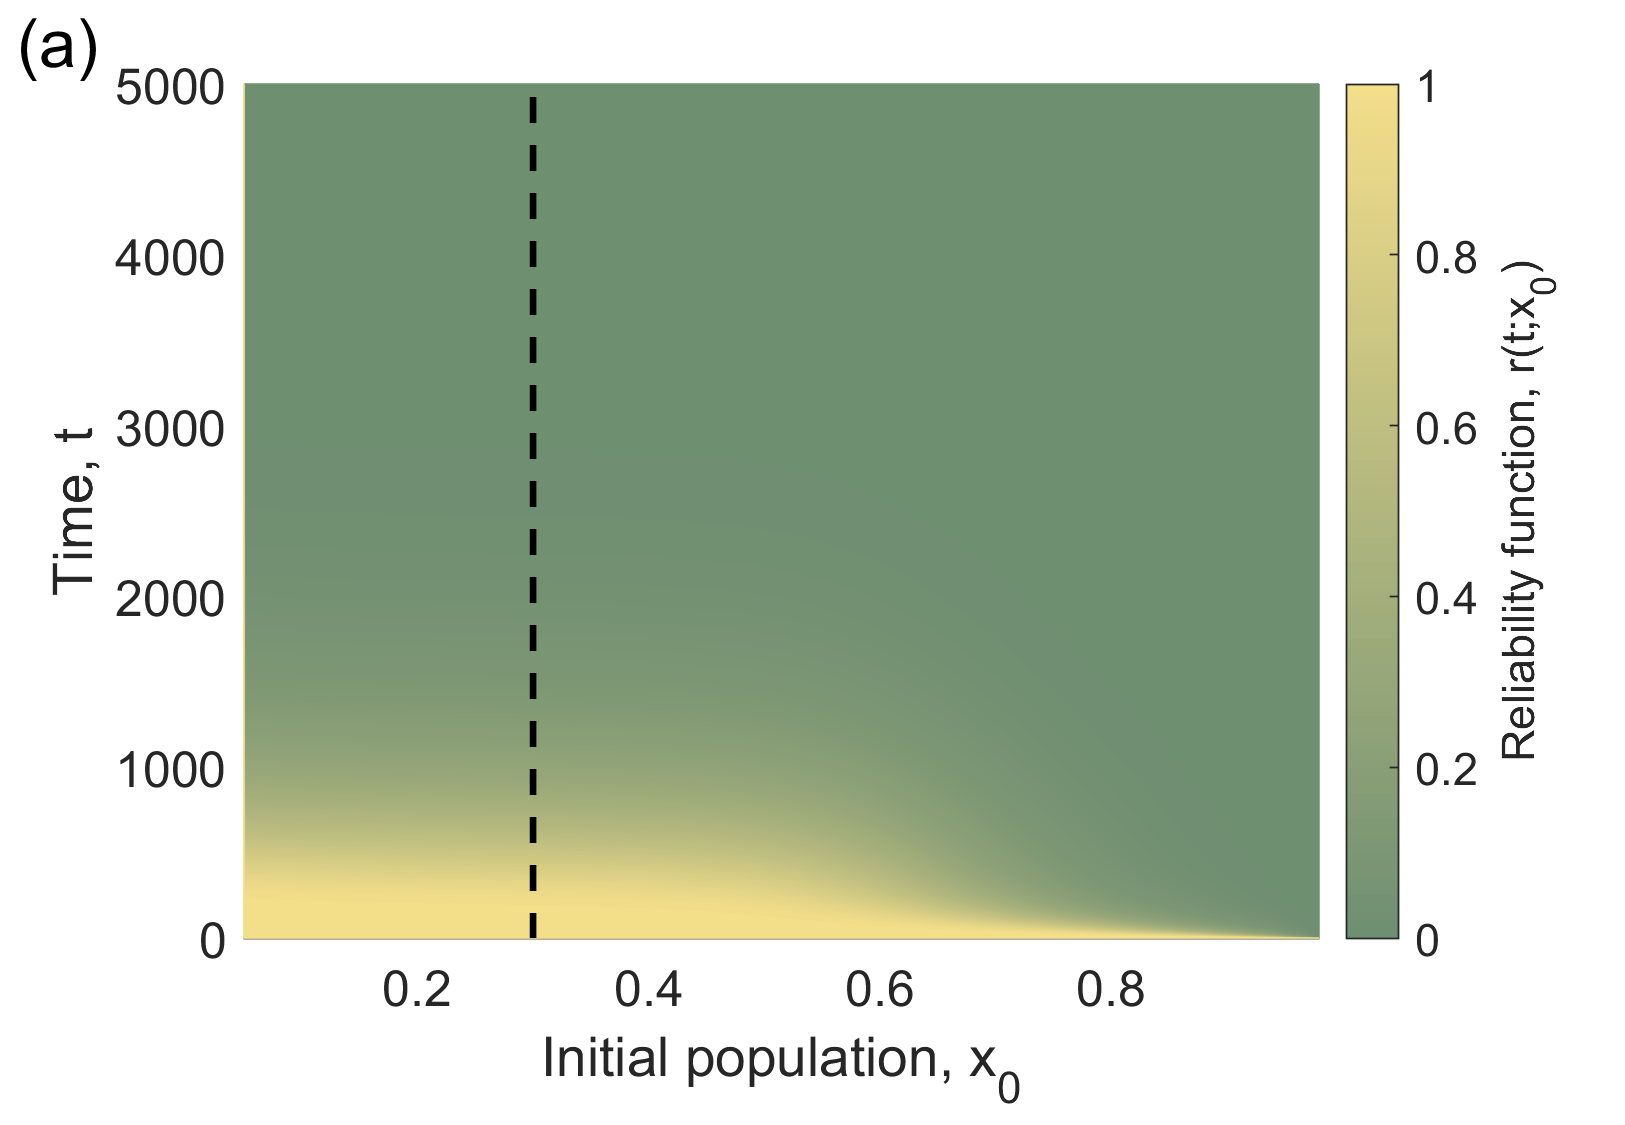


%%%%%%%%%%%%%%%%%%%%%%% Plotting %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
mesh(x0,t,sol); 
view(2);

% create custom colomap
% Number of colors you want between color1 and color2 (including the endpoints)
num_colors = 100;
% Generate the colormap
interpolated_colors = interpolate(color1, color2, num_colors);
% Apply the colormap to your figure
colormap(interpolated_colors);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

c=colorbar;
c.Label.String = 'Reliability function, r(t;x_0)';
hold on;

%Limit & Lable Preferences
xlabel('Initial population, x_0','FontSize',20);
ylabel('Time, t','FontSize',20);
xlim([min(x0),max(x0)]);
ylim([min(t),max(t)]);
zlabel('Probability');
ax = gca; % get current axis handle
ax.FontSize = 15;

%Draw Cross Section
line([xinit, xinit], [0, max(t)], [1, 1],'Color', 'black', 'LineStyle', '--', 'LineWidth', 2);

% Adjust the left margin to increase space on the left side
ax.Position(1) = 0.15; % sets new desired left margin

% Prepare and save figure for publication
width = 650; % Width in pixels
height = 450; % Height in pixels
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size
annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(a)', 'FontSize', 20, 'EdgeColor', 'none');
hold off
exportgraphics(gcf, 'Fig3a.pdf', 'BackgroundColor', 'none');

% Has trouble exporting as vector graphic; large file so still looks a bit grainy

%We Examine the Cross Section Marked in the Above Figure 

% Calculate the absolute differences
abs_diff = abs(x0 - xinit);

% Find the index of the minimum absolute difference
[min_diff, index] = min(abs_diff);

% Get the nearest element from vector x
nearest_element = x0(index);

% Display the result
fprintf('The element in vector x0 nearest to %f is %f at index %d.\n', xinit, nearest_element, index);

The element in vector x0 nearest to 0.300000 is 0.299968 at index 1345.


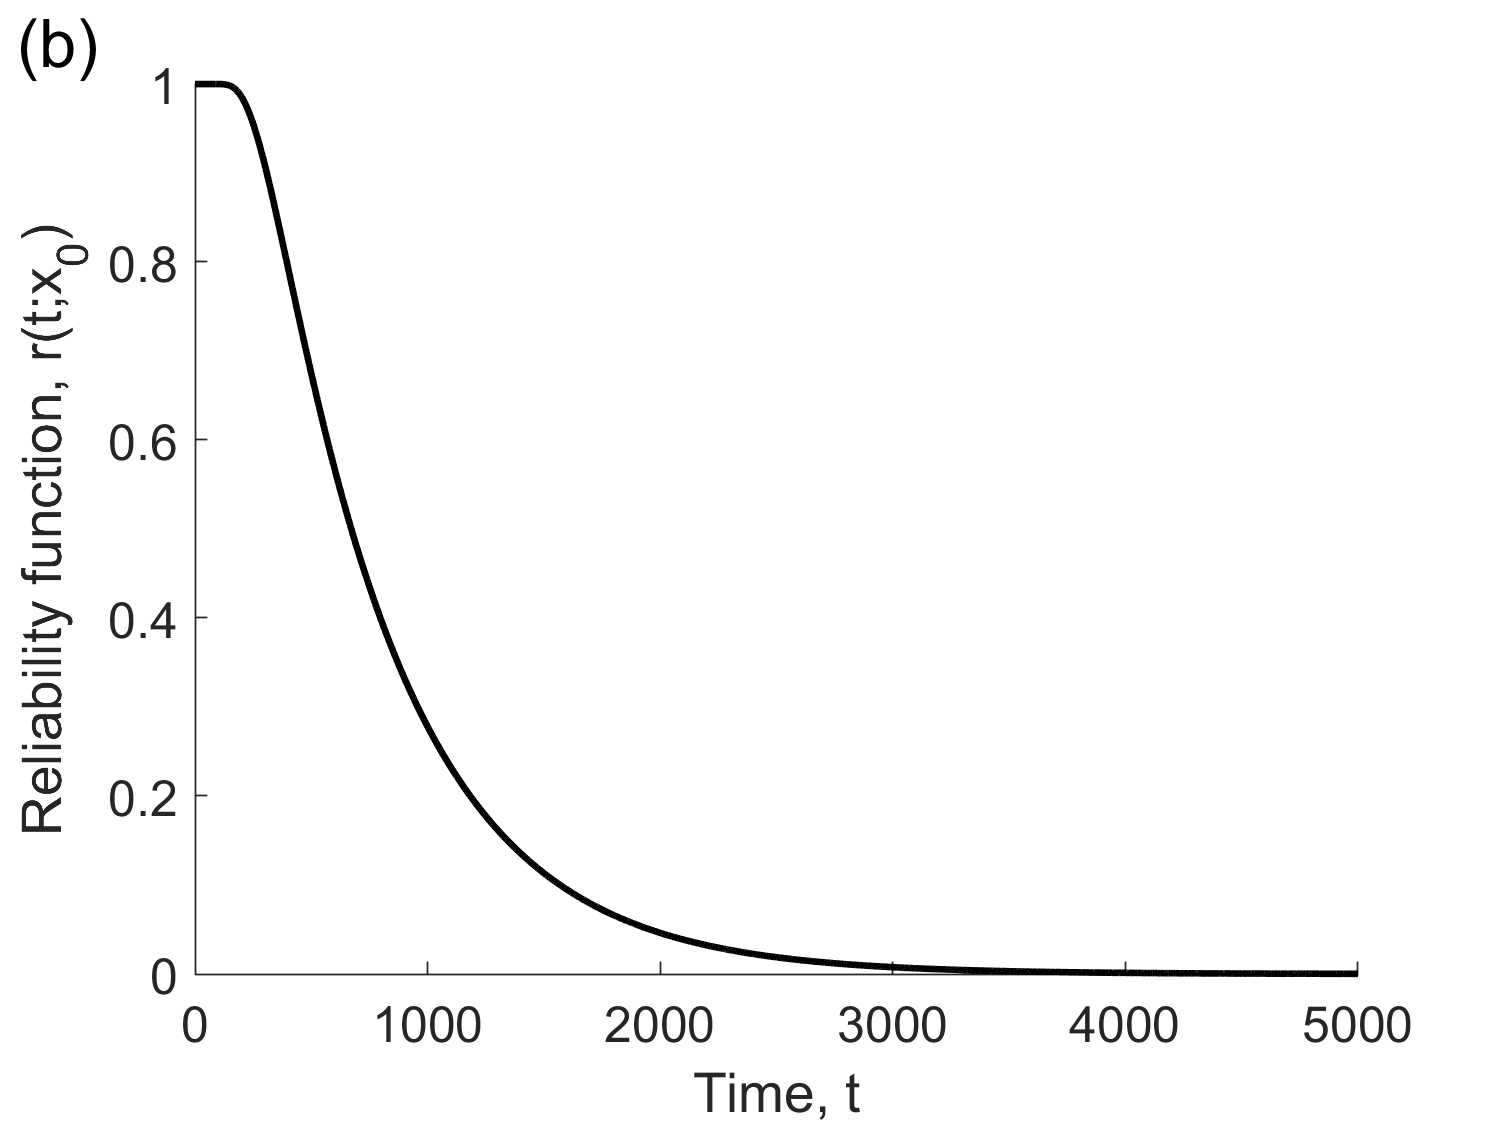


%Retrieve the Reliability Function as the appropriate column in sol
reliability = sol(:,index);

%Plot it & Label it
%nexttile;
figure;
plot(t,reliability,'k','LineWidth',2);
set(gca,'box','off')
xlabel('Time, t','FontSize',20);
ylabel('Reliability function, r(t;x_0)','FontSize',20);
ax = gca; % Get the current axes handle
ax.FontSize = 15;

% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size
annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(b)', 'FontSize', 20, 'EdgeColor', 'none');
exportgraphics(gcf, 'Fig3b.pdf', 'BackgroundColor', 'none');

%We Attain the First Passage Time PDF

%Calculate the pdf (gradient should take a numerical time derivative)
pdf = -gradient(reliability,t);

%Check that the pdf integrates to 1
disp("Observe the integral of this function is: " + trapz(t,pdf));

Observe the integral of this function is: 0.99979


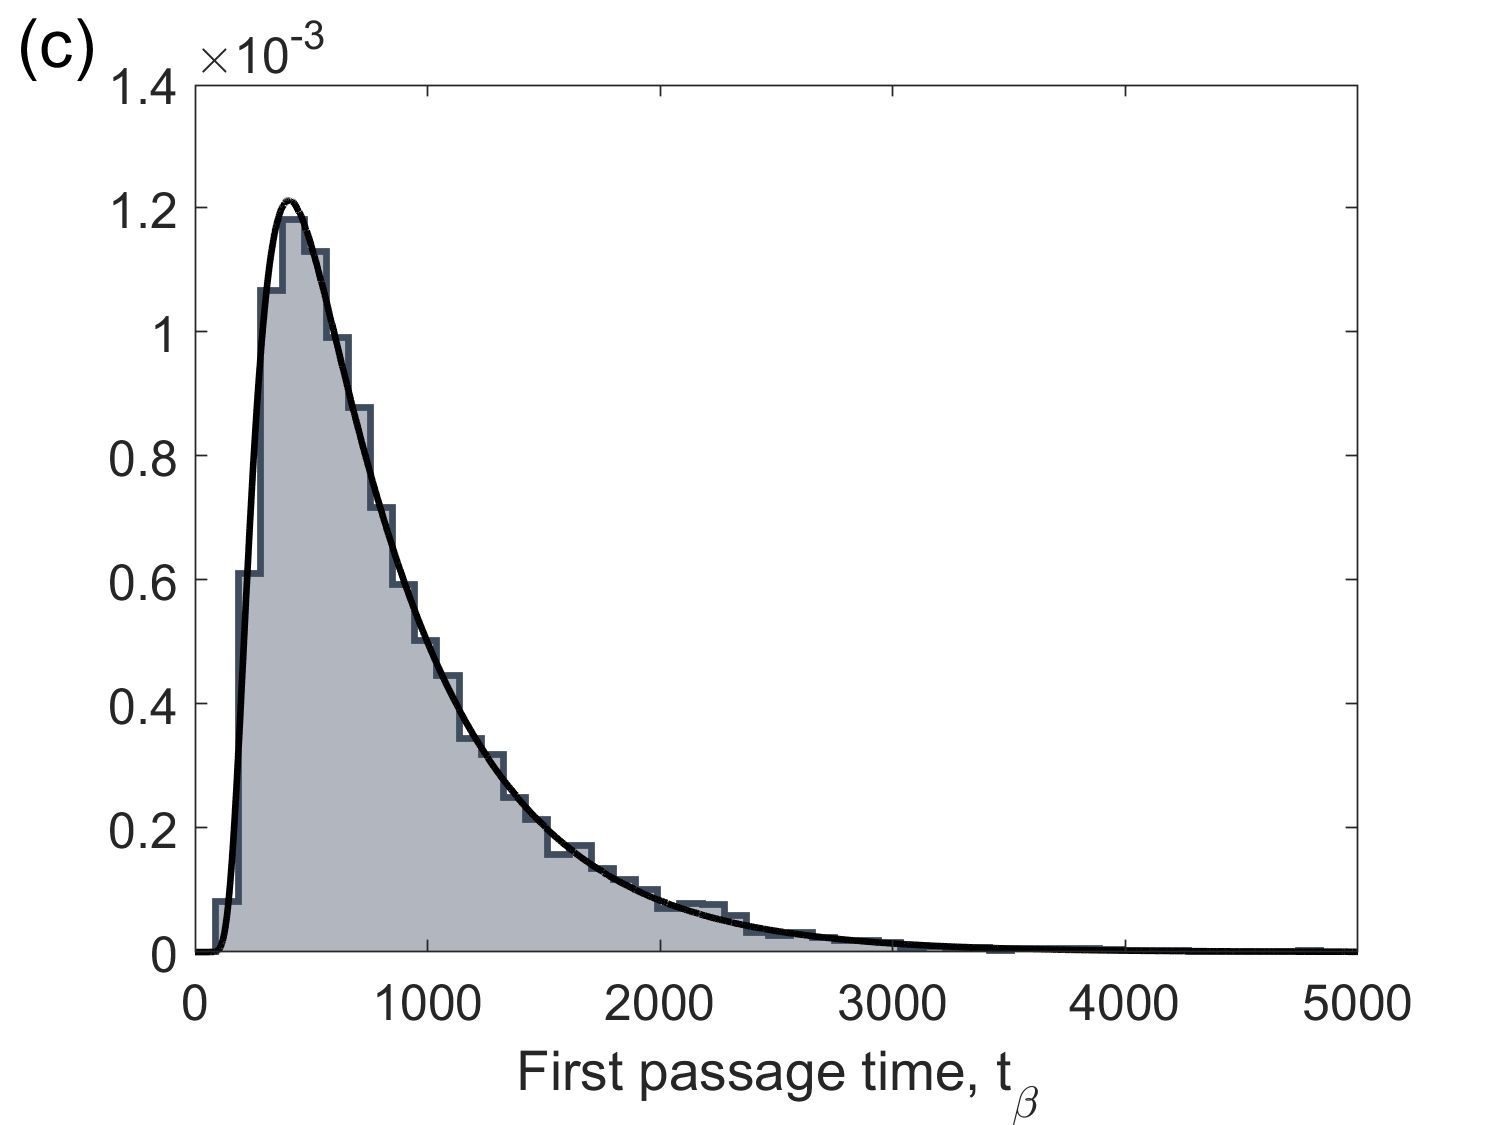


% Overlay histogram from ??? R script
figure;
FPTsims = csvread("simulatedFPTs.csv"); % FPTs generated from Fig3-StochasticTrajectories.Rmd
% Define an RGB color with partial transparency (RGBA)
histogram(FPTsims,50, 'Normalization', 'pdf', 'FaceColor', barColor, 'facealpha' ,0.4,'EdgeColor', 'none');
hold on
histogram(FPTsims,50, 'Normalization', 'pdf', 'DisplayStyle','stairs','EdgeColor', barColor,'LineWidth',2);
 
% Plot pdf 
plot(t,pdf,'k','LineWidth',2);

% Plot details
xlabel('First passage time, t_{\beta}',"FontSize",17);
% ylabel('Probability Density','FontSize',17);
xlim([0 max(t)])
ax = gca;
ax.FontSize = 15;
hold off
% 
% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size
annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(c)', 'FontSize', 20, 'EdgeColor', 'none');
exportgraphics(gcf, 'Fig3c.pdf', 'BackgroundColor', 'none');

% %Plot the CDF of the First Passage Time 
% 
% %Calculate cdf (Integrates Up to Specified t Value, Cumulative Integration)
% cdf = cumtrapz(t,pdf);
% 
% figure;
% plot(t,cdf,'LineWidth',2);
% xlabel('Time',"FontSize",17);
% ylabel('Probability','FontSize',17);

%We Calculate the MFPT

% Make 0 vector of appropriate length
expf = 0*pdf;

% Get X*f(x) points
for i = 1: length(pdf)
    
    expf(i) = pdf(i)*t(i);
end

% Integrate over X*f(x) to get Expectation
expectation = trapz(t,expf);

% Display
disp("The Mean First Passage Time is " + expectation);

The Mean First Passage Time is 831.7103


**Notes on Functions: **eqn is the PDE, u0 is the initial condition function, and bc is the Boundary Condition Functions

function [c,f,s] = eqn(x0,t,P,DPDx0)

%Parameters
global a
[r,K,h,q,sigma] = parameters();

%Time Derivative is Not Scaled
c = 1;

%Diffusion Vector Transformed for BK
f = DPDx0*(.5*sigma^(2)*x0^(2));

%Drift Vector Transformed for BK
s = (r*x0*(1-(x0/K)) - (a*x0^(q))/(x0^(q) + h^(q)) - (sigma^(2) * x0))*DPDx0;

end

function u0 = ic(x0)

%The probability we're in target region at t = 0 is 1 
%Independent of the x0
u0 = 1;

end


function [pl,ql,pr,qr] = bc(x0l,Pl,x0r,Pr,t)

%Probability of Being in Target Space if we Start @ 0 for any time is 1
%given 0 should act like a steady state
pl = 1-Pl;
ql = 0;

%Probability of Being in Target Space if we Start @ mu = 0
pr = Pr;
qr = 0;
end

function interpolated_colors = interpolate(color1, color2, num_colors)
    % Create an array to hold the interpolated colors
    interpolated_colors = zeros(num_colors, 3);
    
    % Calculate the step size for each RGB component
    step = (color2 - color1) / (num_colors - 1);
    
    % Generate the interpolated colors
    for i = 1:num_colors
        interpolated_colors(i, :) = color1 + (i - 1) * step;
    end
end







